Companion software for "Volker Ziemann, *Hands-on Accelerator physics using MATLAB, CRCPress, 2019*" (https://www.crcpress.com/9781138589940)

# Beam-beam tracking (Section 9.7)

Volker Ziemann, 211114, CC-BY-SA-4.0

**Important:** requires the Faddeeva package from [https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions](https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions).

In this example we simulate a so-called **van-der-Meer scan**, where we move one beam transversely across the counter-propagating beam while they are colliding. The electro-magnetic forces cause the closed orbit of the two beams to slighly deform and couples the betatron oscillations of the two beams. We use the parameters of an early version of the B-factory in the PEP tunnel at SLAC where 9 GeV electrons collide with 3.1 GeV positrons.

First we define a few quantities that  we later need to post-process data. Note that we pass some quantities as `global` variables to functions.

clear all; close all;
addpath ./Faddeeva
global Re Rp kapsig Ne Np egamma pgamma Relec
degree=pi/180;
Nfft=1024; tune=(0:Nfft/2-1)/Nfft; % axis for fft plots
Relec=2.8179e-15;        % classical electron radius

Now we define the beam parameters of the electron beam at the interaction point

egamma=9e9/511e3;   % 9 GeV
Ne=3.883e10;  % particles per bunch
emitx=4e-8; betax=1; Qx=0.64; 
emity=2e-9; betay=0.05; Qy=0.57;

and those of the couter-propagating positron bunch.

pgamma=3.1e9/511e3;   % 3.1 GeV
Np=5.632e10;  % particles per bunch
pmitx=4e-8; pbetax=1; pQx=0.64; 
pmity=2e-9; pbetay=0.05; pQy=0.57;

`Re `is the $4\times4$ transfer matrix for the electron beam for one turn in the storage ring and `esigxy` is a $2\times 2$matrix with the horizontal and vertical beam sizes at the IP on the diagonal.

Rx=[cos(2*pi*Qx),betax*sin(2*pi*Qx);-sin(2*pi*Qx)/betax,cos(2*pi*Qx)];  
Ry=[cos(2*pi*Qy),betay*sin(2*pi*Qy);-sin(2*pi*Qy)/betay,cos(2*pi*Qy)]; 
Re=[Rx,zeros(2,2);zeros(2,2),Ry];
esigxy=[emitx*betax, 0; 0, emity*betay]; % electron sigma_xy at IP

`Rp` and `psigxy` are the corresponding quantities for the counter-propagating positron beam.

Rx=[cos(2*pi*pQx),pbetax*sin(2*pi*pQx);-sin(2*pi*pQx)/pbetax,cos(2*pi*pQx)];  
Ry=[cos(2*pi*pQy),pbetay*sin(2*pi*pQy);-sin(2*pi*pQy)/pbetay,cos(2*pi*pQy)]; 
Rp=[Rx,zeros(2,2);zeros(2,2),Ry];
psigxy=[pmitx*pbetax, 0; 0, pmity*pbetay]; % positron sigma_xy at IP

$\Sigma$ or `kapsig` is the sum of the transverse covariance matrices from Equation 9.20.

kapsig=1e12*(esigxy+psigxy);  % KapSigma_xy at IP, converted to micron

Now we are ready to horizontally scan the beams across each other in a** horizontal van-der-Meer scan**. Normally this is accomplished by small dipole magnets or electro-static separators.  After allocating space for a few quantities and defining the bump settings...

pos=zeros(Nfft,1);  % array for positions for FFT
y=zeros(8,1);
bump=-1000:50:1000; 
data=zeros(length(bump),6);

...we a re ready to scan. For each bump setting, we first find the distorted closed orbit with the function `fitco2()`, which is defined below in the Appendix, and store the values for displaying them later. Then we track the two beams with `trak() `and store the horizontal position of beam 1 (the electrons) in the array `pos()`. 

for k=1:length(bump)
  y=fitco2(y,bump(k),0);   % finds closed orbit with beambeam kick
  data(k,1:4)=[y(1),y(2),y(5),y(6)];  % store orbits for later display
  y(1)=y(1)+10;  % excite a betatron oscillation with 10 micron amplitude
  for m=1:Nfft   % iterate to get tunes from FFT
    y=trak(y,bump(k),0); pos(m)=y(1);
  end

From the stored position we determine the tunes of the coupled system by Fourier-transforming` pos()` with `fft()` and finding the peaks, which we store in the array `data` for later display.

  [peaks,locs]=findpeaks(2*abs(fft(pos))/Nfft,'MinPeakHeight',2);
  data(k,5)=(locs(1)-1)/Nfft; data(k,6)=(locs(2)-1)/Nfft;
end

Once the whole range of bump settings is done, we plot the data against the bump amplitude. The upper plot shows the deflection angle of the electron and positron bunches. Note the opposite sign and the slightly different magnitudes, which is caused by the different number of particles in the bunches and the different energies of the counter-propagating bunches.

subplot(2,1,1); plot(bump,data(:,2),'k',bump,data(:,4),'r-.');
xlabel('Horizontal bump amplitude [\mum]')
ylabel('Deflection angle [\murad]')
legend('Electrons','Positrons')

The lower plot shows the tunes detrmined by the call to fft(). We note that for large bunch offsets the tunes are almost equal, ebcause the bunches miss each other and do not couple. But once they are close, the beam-beam interaction couples the tunes and we see that one mode stay at the unperturbed values, while the other deviates significantly. The maximum split of the two modes occurs when the beams are colliding head-on, which is used in colliders to determine the best position of the colliding beams.

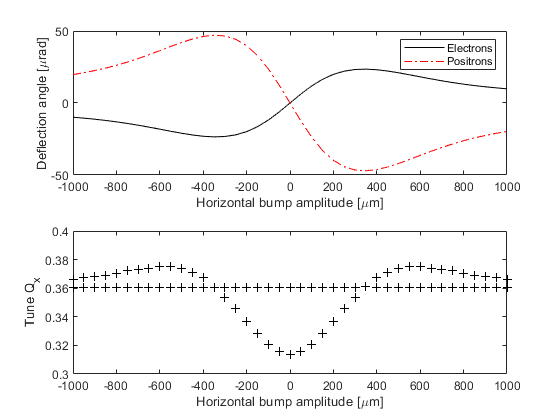

subplot(2,1,2); plot(bump,data(:,5),'k+',bump,data(:,6),'k+'); 
xlabel('Horizontal bump amplitude [\mum]'); ylabel('Tune Q_x')
ylim([0.3,0.4]); 

A **vertical van-der-Meer** scan works in much the same way as the horizontal one. We first allocate variables and define the bump amplitude.

figure
y=zeros(8,1);
bump=-100:5:100;
data=zeros(length(bump),4);

An then loop over the different bump settings. At each setting we first determine the closed orbit with fitco2(), store the values and follow a slightly excited bunch for Nfft turn, while storing the vertical position.

for k=1:length(bump)
  y=fitco2(y,0,bump(k));   % finds closed orbit with beambeam kick
  data(k,1:4)=[y(3),y(4),y(7),y(8)];   % store vertical orbits
  y(3)=y(3)+10;  % excite a vertical betatron oscillation
  for m=1:Nfft   % iterate to get tunes from FFT
    y=trak(y,0,bump(k)); pos(m)=y(3);
  end

As before, we the determine the tunes from the FFT, but have to take care of aliasing, because the vertical tunes are above the half integer.

  [peaks,locs]=findpeaks(2*abs(fft(pos))/Nfft,'MinPeakHeight',0.5);
  Q1=(locs(1)-1)/Nfft; if Q1>0.5 Q1=1-Q1; end  % avoid aliasing
  Q2=(locs(2)-1)/Nfft; if Q2>0.5 Q2=1-Q2; end
  data(k,5)=Q1; data(k,6)=Q2;
end

And finally, we plot the deflection angle at the interaction point in the upper plot and the tunes in the lower plot.

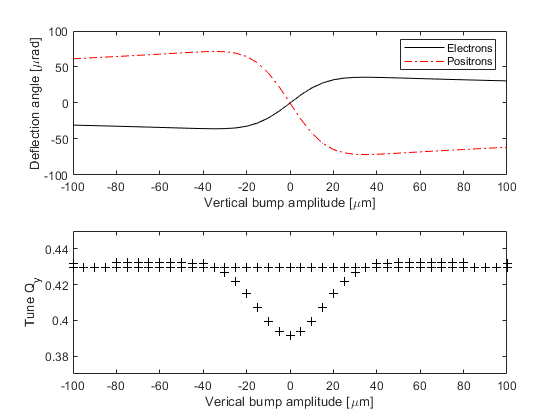

subplot(2,1,1); plot(bump,data(:,2),'k',bump,data(:,4),'r-.');
xlabel('Vertical bump amplitude [\mum]')
ylabel('Deflection angle [\murad]')
legend('Electrons','Positrons')
subplot(2,1,2); plot(bump,data(:,5),'k+',bump,data(:,6),'k+'); 
xlabel('Verical bump amplitude [\mum]'); ylabel('Tune Q_y')
ylim([0.37,0.45]); 

## Appendix

The function` fitco2()` determines the closed  orbit distortion from the combined effect of the bump and the beam-beam deflections, where the latter depend non-linearly on the positions, which makes some iterations necessary. 

function y=fitco2(y,xbump,ybump)
global Re Rp kapsig Ne Np egamma pgamma Relec
RSe=inv(eye(4)-Re)*Re;
RSp=inv(eye(4)-Rp)*Rp;
ic=20;     % iteration counter
while ic>0   
  ic=ic-1;
  xsep=y(1)-y(5)+xbump;    % separation between bunch centers
  ysep=y(3)-y(7)+ybump;
  q=F0(xsep,ysep,kapsig);   % the beam beam kick
  xk=imag(q); yk=real(q);  
  exdef=-2e12*Relec*Np*xk/egamma;    % electron deflection angle
  eydef=-2e12*Relec*Np*yk/egamma;    
  pxdef=2e12*Relec*Ne*xk/pgamma;     % positron deflection angles
  pydef=2e12*Relec*Ne*yk/pgamma;
  y(1:4)=RSe*[0;exdef;0;eydef];
  y(5:8)=RSp*[0;pxdef;0;pydef];
end
end

The function trak() implements one turn of the combined system of the two counter-propagating beams including the bumps and the beam-beam interactions. It just receives the $2\times 4$ input coordinates $x,x',y,y'$ for each beam and returns those positions after one turn.  

function y=trak(y,xbump,ybump)
global Re Rp kapsig Ne Np egamma pgamma Relec
xsep=y(1)-y(5)+xbump;     % separation between bunch centers
ysep=y(3)-y(7)+ybump;
q=F0(xsep,ysep,kapsig);   % the beam beam kick
xk=imag(q); yk=real(q);  
exdef=-2e12*Relec*Np*xk/egamma;    % electron deflection angle
eydef=-2e12*Relec*Np*yk/egamma;    
pxdef=2e12*Relec*Ne*xk/pgamma;     % positron deflection angles
pydef=2e12*Relec*Ne*yk/pgamma;
y(2)=y(2)+exdef; y(4)=y(4)+eydef;  % electron deflection angle
y(6)=y(6)+pxdef; y(8)=y(8)+pydef;  % Positron deflection angle
y(1:4)=Re*y(1:4);  % electron transport through the ring
y(5:8)=Rp*y(5:8);  % positron transport through the ring
end

The beam-beam kick depends on the function `F0()`, defined in Equation 9.28. It uses the complex error function $w(z)$ which is provided by the Faddeeva package from matlab central ([https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions](https://www.mathworks.com/matlabcentral/fileexchange/38787-faddeeva-package-complex-error-functions)).

function out=F0(x,y,sig)
r=1/sqrt(2*(sig(1,1)-sig(2,2)+2*i*sig(1,2)));
detsig=sig(1,1)*sig(2,2)-sig(1,2)^2;
if abs(r) > 1e8      % round beam
    out=i*(x-i*y).*(1-exp(-0.5*(x.^2+y.^2)./sig(1,1)))./(x.^2+y.^2+1e-10);
    return
end
a1=r;
a2=i*r;
b1=r*(sig(2,2)-i*sig(1,2))/sqrt(detsig);
b2=i*r*(sig(1,1)+i*sig(1,2))/sqrt(detsig);
g=0.5*(sig(2,2)*x.^2-2*sig(1,2).*x.*y+sig(1,1)*y.^2)/detsig;
z1=a1*x+a2*y;
z2=b1*x+b2*y;
zz1=conj(z1);
zz2=conj(z2);
q1=(imag(z2)>=0);  % use one or the other form , depending on sign of
q2=1-q1;           % imaginary part of argument of w(z)
out1=Faddeeva_w(z1)-exp(-g).*Faddeeva_w(z2);
out1(isnan(out1))=0; out1(isinf(out1))=0;
out2=conj(Faddeeva_w(zz1)-exp(-g).*Faddeeva_w(zz2));
out2(isnan(out2))=0; out2(isinf(out2))=0;
out=sqrt(pi)*r*(q1.*out1-q2.*out2);
end